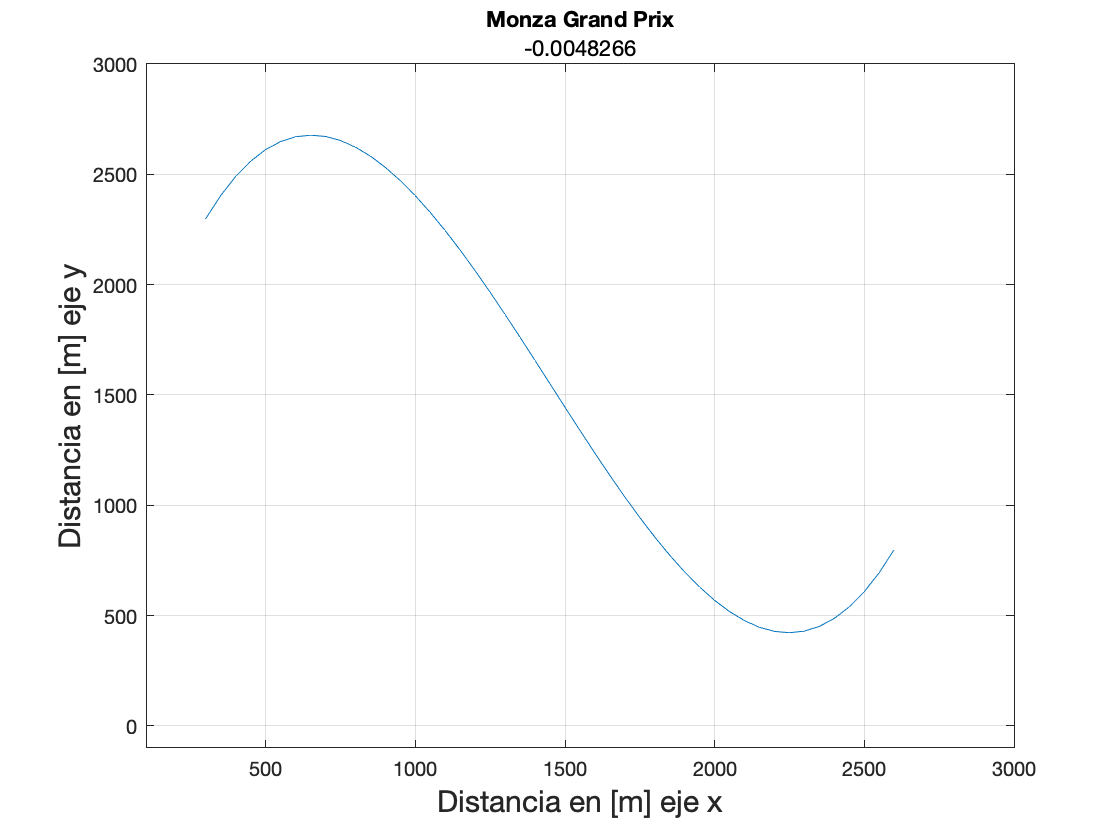

 close all;
clear;
clc;

%Puntos de la curva en matrices
px = [300,1066.67,1833.34,2600];
py = [2300,2300,800,800];
 


%Asigna los valores de los puntos a las variables 
coeficientes = polyfit(px, py,3);
a = coeficientes (1);
b = coeficientes (2);
c = coeficientes (3);
d = coeficientes (4);

%y = 0.9927*10^-6x^3 - 0.0039x^2 + 3.0367x + 1747.0415--> ecuación de la
%curva

% Variables para los axis


pasoX = 50;
x = [px(1):pasoX:px(4)];
y = (a.*(x.^3) + b.*(x.^2) + c.*(x) + d );

maxX = max(x);
minX = min(x);

inicioX = px(1) - 200;
finalX = px(4)+ 400;
inicioY = minX - 400;
finalY = maxX + 400;


figure (1);
plot (x,y);
grid on;
title ('Monza Grand Prix', b);
xlabel ('Distancia en [m] eje x', 'FontSize',15);
ylabel ('Distancia en [m] eje y','FontSize',15);


%Imprimir los coeficientes
axis([inicioX finalX inicioY finalY]); 

fprintf('Coeficientes = %4.10fx^3 %4.10fx^2 %4.10fx %4.10f \n', coeficientes);

Coeficientes = 0.0000011096x^3 -0.0048265608x^2 4.8789659687x 1240.7427606026 
